clear all;
close all;
addpath('PIVLAB\')

% init
bos = PLBOSS( ...
    back="sampledata\im_1.tif", ...
    dir="sampledata", ...
    file="*_2.tif");

PLBOSS.PREPBACKGROUND: pre-processing background ...OK



return;

## example

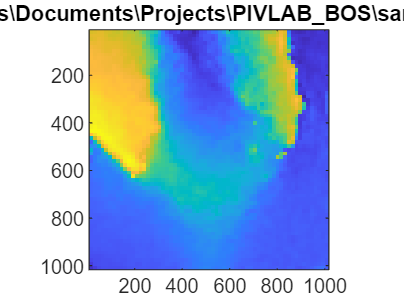

% analyze
bos = bos.Analyze;

% show
figure;
bos.Show;

## Parallel analysis

parfor ii = 1:8
    bospar = bos;
    bospar = bospar.Analyze(framenum=1);
end


## Change Settings

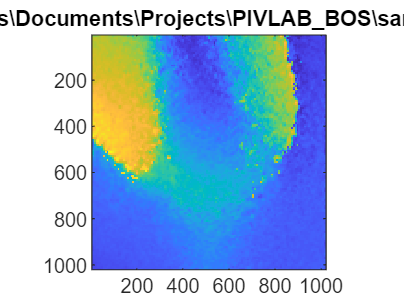

bos = bos.Set_Settings(NumPasses=3);
bos = bos.Analyze;

% show
figure;
bos.Show;